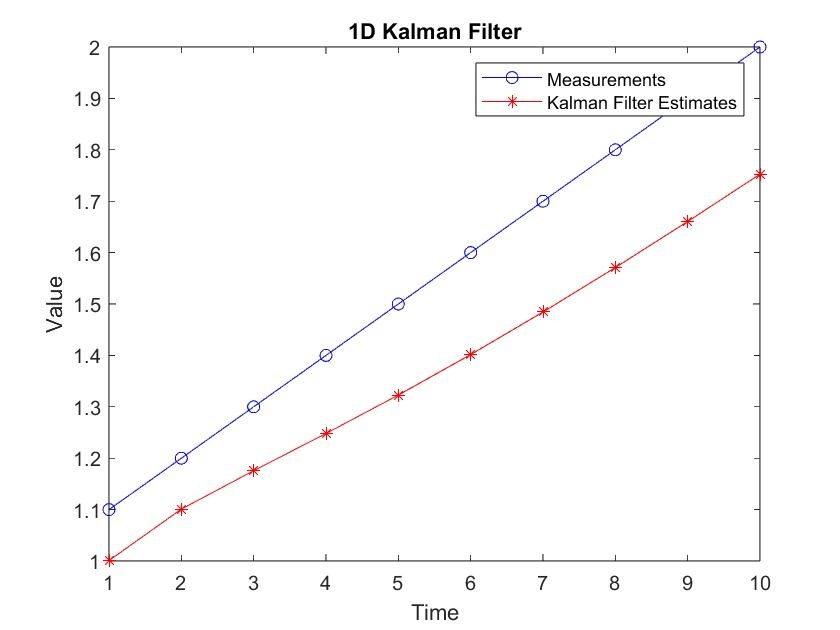

% Define the initial state estimate
x_estimate = 0;

% Define the initial estimate error covariance
P = 1;

% Define the process noise covariance
Q = 0.01;

% Define the measurement noise covariance
R = 0.1;

% Define the measurement
measurement = [1.1, 1.2, 1.3, 1.4, 1.5,1.6,1.7,1.8,1.9,2.0];

% Preallocate arrays to store results
x_estimates = zeros(size(measurement));
P_estimates = zeros(size(measurement));

for k = 1:length(measurement)
    % Prediction Step
    x_predict = x_estimate;
    P_predict = P + Q;
    % Update Step
    K = P_predict / (P_predict + R);
    x_estimate = x_predict + K * (measurement(k) - x_predict);
    P = (1 - K) * P_predict;

    % Store the estimates
    x_estimates(k) = x_estimate;
    P_estimates(k) = P;
end

% Plot the results
time = 1:length(measurement);
plot(time, measurement, 'bo-', time, x_estimates, 'r*-');
legend('Measurements', 'Kalman Filter Estimates');
xlabel('Time');
ylabel('Value');
title('1D Kalman Filter');